clear all;
f = @(x) x(1)-(4.*(x(1)+x(2)).*exp(-x(1).^2 - x(2).^2)+0.1).^2

f = function_handle with value:
    @(x)x(1)-(4.*(x(1)+x(2)).*exp(-x(1).^2-x(2).^2)+0.1).^2


f_odwr = @(x) -f(x);
f_due = @(x1, x2) x1-(4.*(x1+x2).*exp(-x1.^2 - x2.^2)+0.1).^2

f_due = function_handle with value:
    @(x1,x2)x1-(4.*(x1+x2).*exp(-x1.^2-x2.^2)+0.1).^2


f_wrap = @(x) f_due(x(1, :), x(2, :))

f_wrap = function_handle with value:
    @(x)f_due(x(1,:),x(2,:))



[X,Y] = meshgrid(-0.6:.05:0.6);
Z = f_due(X, Y)

Z =    -5.6015   -5.7101   -5.7475   -5.7083   -5.5897   -5.3923   -5.1201   -4.7800   -4.3821   -3.9387   -3.4638   -2.9721   -2.4788   -1.9979   -1.5422   -1.1221   -0.7458   -0.4184   -0.1424    0.0825    0.2589    0.3915    0.4862    0.5500    0.5900
   -5.7601   -5.8526   -5.8691   -5.8047   -5.6573   -5.4286   -5.1235   -4.7505   -4.3208   -3.8482   -3.3479   -2.8359   -2.3279   -1.8386   -1.3809   -0.9652   -0.5992   -0.2873   -0.0310    0.1711    0.3228    0.4300    0.4998    0.5400    0.5587
   -5.8475   -5.9191   -5.9108   -5.8182   -5.6402   -5.3794   -5.0422   -4.6384   -4.1806   -3.6838   -3.1643   -2.6392   -2.1246   -1.6357   -1.1852   -0.7833   -0.4367   -0.1489    0.0796    0.2518    0.3726    0.4493    0.4900    0.5037    0.4993
   -5.8583   -5.9047   -5.8682   -5.7451   -5.5356   -5.2433   -4.8761   -4.4450   -3.9641   -3.4495   -2.9185   -2.3887   -1.8770   -1.3983   -0.9650   -0.5865   -0.2688   -0.0140    0.1790    0.3143    0.3985    0.4400    0.4484    0.4334   

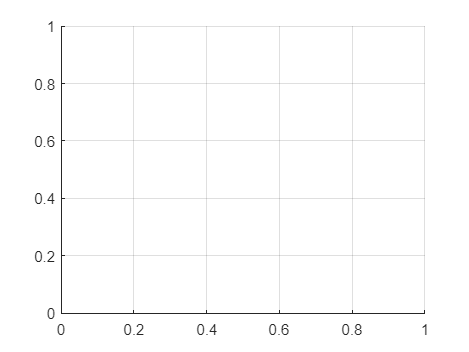

%mesh(X,Y,Z)
grid on;


P1= [-1,-1];
P2= [0,0];
P3= [3,3];
P4= [-0.8,1];

s = 0.5;  %  długość kroku

alpha = 0.5;  % zmniejszenie kroku po niepowodzeniu

epsilon = 1e-6;  % dokładność

contour(X,Y,Z, 100)
hold on;
x = HJ(f, P1, s, alpha, epsilon, 2)

x =    -0.5334   -0.4890


plot(x(1), x(2), '+');
x = HJ(f, P2, s, alpha, epsilon, 2)

x =     0.4694    0.5103


plot(x(1), x(2), '+');
x = HJ(f, P3, s, alpha, epsilon, 2)

x =    -0.5334   -0.4890


plot(x(1), x(2), '*');
x = HJ(f, P4, s, alpha, epsilon, 2)

x =     0.4694    0.5103


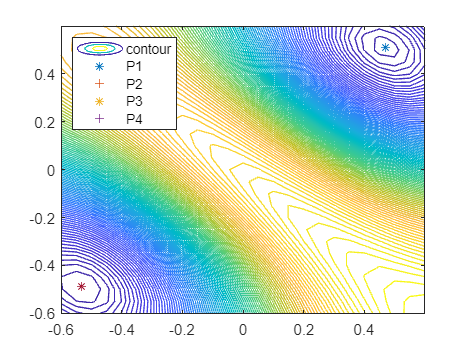

plot(x(1), x(2), '*');
legend(["contour", "P1", "P2", "P3", "P4"], Location="northwest");

function [new_x] = HJ_try(f, x, s, baza)
    for e = baza
        e = e';
        if f(x + s*e) < f(x)
            x = x + s.*e;
        else
            if f(x - s*e) < f(x)
                x = x - s.*e;
            end %if
        end %if
    end %while
    new_x = x;
end %HJ_try


function [x] = HJ(f, x, s, alpha, epsilon, dim)
    baza = eye(dim, dim);
    x_vec = [x];
    i = 2;
    while s>epsilon
        x_b = x;
        x = HJ_try(f, x_b, s, baza);
        if f(x) < f(x_b)
    
            while f(x) < f(x_b)
                xx_b = x_b;
                x_b = x;
                x = 2*x_b - xx_b;
                x = HJ_try(f, x, s, baza);
            end %while
            
            x = x_b;
        else %if
            s = alpha * s;
            
        end %if
    end %while
    x = x_b;
end %HJ_try